# One versus one

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus one (OVO) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train a set of OVO SVMs on the whole dataset, with default parameters [3 marks]

- An appropriate call to train a *second* set of OVO SVMs on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVMs()` function to give a helpful visualisation of any 2D model trained by the `fitcecoc()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Using the `visualiseSVMs()` function you have developed to produce a visualisation of each of the two sets of SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

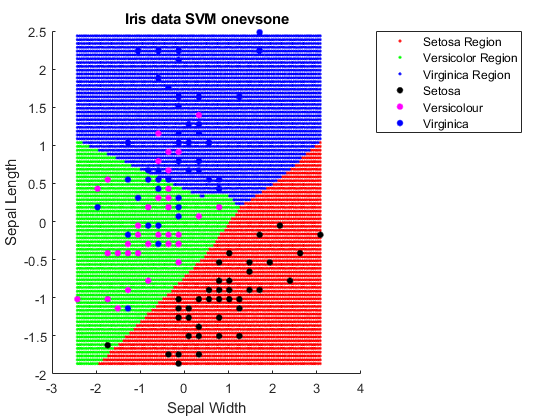

% add as many lines of code as you need below:

% train 1v1 SVM on the whole dataset with default parameters:
m = fitcecoc(examples, labels, 'Coding', 'onevsone');

% setup a template for implementing a non default SVM:
t = templateSVM('KernelFunction','rbf','KernelScale', 0.4);

% train a second 1v1 SVM on the whole dataset using non default template:
m2 = fitcecoc(examples, labels, 'Coding', 'onevsone', 'Learners', t);

% call the visualise SVM function to display the results visually:
visualiseSVMs(m, examples, labels)

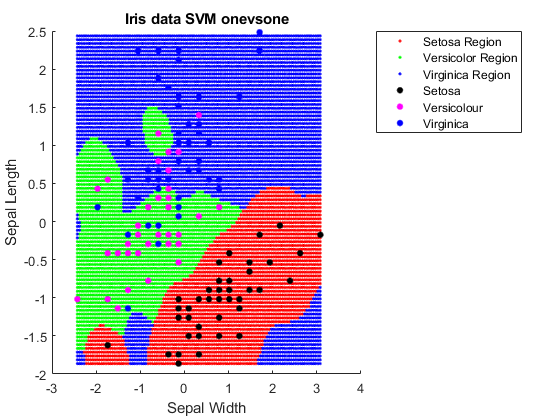

figure
visualiseSVMs(m2, examples, labels)

function visualiseSVMs(m, examples, labels)
    
    hold on
    
    % find the min and the max of both columns in example data
    min1 = min(examples{:,1});
    max1 = max(examples{:,1});
    min2 = min(examples{:,2});
    max2 = max(examples{:,2});
    
    
    % create an array to hold the grid of visualisation points
    generatedExamples = [];
    
    % create nested for loop to loop from the min and the max of each column
    for i=min1:0.05:max1
        for j=min2:0.05:max2
            % add each value in the grid to the array
            generatedExamples = [generatedExamples; [i j]];
        end
    end
    
    % predict the outcome of each set of values in the grid
    gridpredictions = predict(m, generatedExamples);
    % plot the points and their corresponding predictions
    gscatter(generatedExamples(:,1),generatedExamples(:,2),gridpredictions, 'rgb')
    
    % plot the original datapoints to visualize the classifiers accuracy:
    gscatter(examples{:,1},examples{:,2},labels, 'kmb')
    % add x and y labels and a legend to ensure clarity:
    xlabel("Sepal Width")
    ylabel("Sepal Length")
    title("Iris data SVM onevsone")
    legend('Setosa Region','Versicolor Region', 'Virginica Region', 'Setosa','Versicolour', 'Virginica', 'Location', "bestoutside");
 
    hold off

end